clear
load yface10.mat

A = tensor(yface10(:,1:8,:)); % Matlab tensor data
A1 = double(tenmat(A, 1));
A2 = double(tenmat(A, 2));
A3 = double(tenmat(A, 3));

[F, s1, v] = svd(A1, 'econ');
[G, s2, v] = svd(A2, 'econ');
[H, s3, v] = svd(A3, 'econ');
k=10;
Fk = F(:,1:k);
clear s1 s2 s3 v

% Compute core
S = ttm(A, {F', G', H'});

% All orthogonality check
%sum(sum(double(S(2,:,:).*S(3,:,:))))

%C = ttm(S, {F, G}, [1 2]);
%Ck = ttm(S, {G}, [2]);
%Ck = ttm(Ck(1:k,:,:), Fk, 1);

B = ttm(S, G, 2);
Bk = B(1:k,:,:);

% Pre process QR
for e=1:size(B,2)
    [q, r] = preprocess(double(B), e);
    Q{e} = q;
    R{e} = r;
end


for e=1:size(Bk,2)
    [q, r] = preprocess(double(Bk), e);
    Qk{e} = q;
    Rk{e} = r;
end

% Program testing
selectedPerson = 4;%input("Select person");
selectedExpression = 10;
testImage = getImage(selectedExpression, selectedPerson, yface10);

tolerance = 0.75;

[person1, expression1] = classify(testImage, Q, R, tolerance, F, H)

person1 = 4

expression1 = 1

[person2, expression2] = classify(testImage, Qk, Rk, tolerance, Fk, H)

person2 = 4

expression2 = 6


disp('Selected person')

Selected person


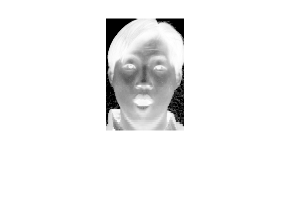

imshow(reshape(testImage, 112, 78), [])

Predicted person full rank


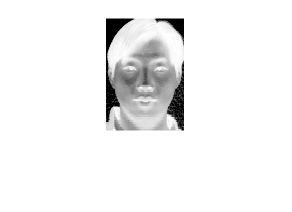


if(person1 ~= -1)
    disp('Predicted person full rank')
    predictedImage = getImage(1,person1, yface10);
    imshow(reshape(predictedImage, 112, 78), [])
else
    disp('Person not found with full rank')
end

Predicted person low rank



if(person2 ~= -1)
    disp('Predicted person low rank')
    predictedImage = getImage(1,person2, yface10);
    imshow(reshape(predictedImage, 112, 78), [])
else
    disp('Person not found with lower rank')
end

function [person, expression] = classify(testimage, Q, R, tol, F, H)
   person = -1;
   expression = -1;
   zhat = F'*testimage;
    
   for e=1:8
        solution = R{e} \ (Q{e}' * zhat);
        for p=1:10
            if(norm(solution - H(p,:)') < tol)
                person = p;
                expression = e;
                return
            end
        end
   end
end

function [q, r] = preprocess(b, e)
        [q, r] = qr(squeeze(b(:,e,:)), 0);
end

function im = getImage(e, p, data)
    im = data(:, e, p);
end